**步骤1：加载图像数据，并将其划分为训练集和验证集**

% 加载图像数据
digitDatasetPath = fullfile('C:', 'Users', 'Lindean', 'Documents', 'digital_image_processing', ...
   'EuroSat','2750' );
imds = imageDatastore('C:\Users\Lindean\Documents\digital_image_processing\EuroSAT\2750', ...
    'IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\digital_image_processing\EuroSAT\2750\AnnualCrop\AnnualCrop_1.jpg';
                              ' ...\digital_image_processing\EuroSAT\2750\AnnualCrop\AnnualCrop_10.jpg';
                              ' ...\digital_image_processing\EuroSAT\2750\AnnualCrop\AnnualCrop_100.jpg'
                               ... and 26997 more
                              }
                     Folders: {
                              'C:\Users\Lindean\Documents\digital_image_processing\EuroSAT\2750'
                              }
                      Labels: [AnnualCrop; AnnualCrop; AnnualCrop ... and 26997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
   

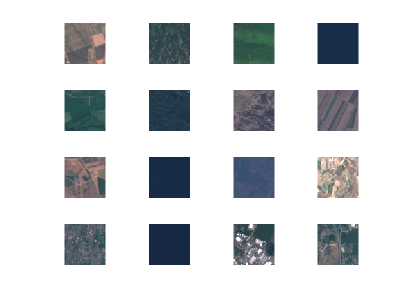


% 划分验证集和训练集
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

% 随机显示训练集中的部分图像
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

**步骤2：加载预训练好的网络**

% 加载alexnet网络（注：该网络需要提前下载，当输入下面命令时按要求下载即可）
net = alexnet;
% net=googlenet

**步骤3：对网络结构进行改进**

% 保留AlexNet倒数第三层之前的网络
layersTransfer = net.Layers(1:end-3);

% 确定训练数据中需要分类的种类
numClasses = numel(categories(imdsTrain.Labels));

% 构建新的网络，保留AlexNet倒数第三层之前的网络，在此之后重新添加了全连接
layers = [
    layersTransfer                                       % 保留AlexNet倒数第三层之前的网络
    fullyConnectedLayer(numClasses)                      % 将新的全连接层的输出设置为训练数据中的种类
    softmaxLayer                                         % 添加新的Softmax层
    classificationLayer ];

**步骤4：调整数据集**

% 查看网络输入层的大小和通道数
inputSize = net.Layers(1).InputSize;

% 将训练图像的大小调整为与输入层的大小相同
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
% 将验证图像的大小调整为与输入层的大小相同
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

**对网络进行训练**

% 对训练参数进行设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',15, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',0.00005, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',true, ...
    'Plots','training-progress');

% 用训练图像对网络进行训练
    netTransfer = trainNetwork(augimdsTrain,layers,options);

**分类验证图像并并随机显示分类结果**

% 对训练好的网络采用验证数据集进行验证
[YPred,scores] = classify(netTransfer,augimdsValidation);

% 随机显示验证效果
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

**计算分类准确率**

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

**创建并显示混淆矩阵**

figure
confusionchart(YValidation,YPred)